# Example 1: executing a simulation 

### This assumes the database and default data has been set up

## 1. add directory contents to exec path, connect to db

% get the root directory
file_path = strsplit(fileparts(matlab.desktop.editor.getActiveFilename), filesep);
idx = find(strcmp(file_path, 'uavtestbed'));
root_directory = strjoin(file_path(1:idx), filesep);
% switch to the root directory
cd(root_directory);

% load the workspace paths
addpath(genpath(root_directory));
clear('file_path', 'idx', 'root_directory');

% load the api
api = jsondecode(fileread('sql/api.json'));

username=input('username: ', 's');
password=input('password: ', 's');
db_name = 'uav2_db';

%the database connection
% conn = postgresql(username, password, "Server", 'localhost', "PortNumber", 5432, "DatabaseName", 'uav2_db');
conn = database(db_name, username, password);

## 2. Retrieve UAV and basic info from db

- flight num / flight id

- last timestamp

- stop codes and group ids

% check out what UAVs are in the db
uav_tb = select(conn, api.matlab.assets.LOAD_ALL_UAVS)

uav_tb = 2×17 table
     age      serial_number       common_name       id    airframe_id    battery_id    m1_id    m2_id    m3_id    m4_id    m5_id    m6_id    m7_id    m8_id    gps_id    max_flight_time    dynamics_srate
    ______    _____________    _________________    __    ___________    __________    _____    _____    _____    _____    _____    _____    _____    _____    ______    _______________    ______________

% load the UAV 
% note, the default UAV is not supported any more and some functionality
% below will be skipped if using the default uav (recommended to use the tarot)
uav = load_uav(conn, uav_tb.serial_number{2}, api);

% uav = load('params/uav.mat').uav;
uav

uav = struct with fields:
                uav: [1×1 struct]
           airframe: [1×1 struct]
            battery: [1×1 struct]
             motors: [8×1 struct]
                gps: [1×1 struct]
    max_flight_time: 15
                 id: 24
               mass: 10.6600
     dynamics_srate: 0.0250


### Load the stop_code_tb and group_tb

% to match stop codes with the simulation
% new stop codes for your specific experiment can be created
stop_code_tb = select(conn, "select * from stop_code_tb;")

stop_code_tb = 6×2 table
    id           description        
    __    __________________________

    1     {'low soc'               }
    2     {'low voltage'           }
    3     {'max position error'    }
    4     {'arrival success'       }
    5     {'average position error'}
    6     {'low soh (battery)'     }


% for organizing multiple executions
group_id_tb = select(conn, "select * from group_tb")

group_id_tb = 1×2 table
    id        info    
    __    ____________

    1     {'examaple'}


group_id = group_id_tb.id(1);

### Look at the flight summary table and get the last timestamp and flight_id

- since these are simulations, the simulation time will grow beyond real time so we cannot just use " datestr(now) " as the start time

- The start time is important because the telemetry data is indexed via timestamp

- the start and stop timestamps in the flight_summary_tb are used to access the flight telemetry data for that flight

- the flight_id refers to the id field of flight_summary_tb

% get the start time
dt_last = table2array(select(conn, 'select mt.dt_stop from flight_summary_tb mt order by dt_stop desc limit 1;'));
if ~isempty(dt_last)
    dt_last = datetime(dt_last);
end

if isempty(dt_last)
    % the first entry into flight_summary_tb is now
    dt_start = datetime(now, 'ConvertFrom', 'datenum');
else
    % this entry into flight_summary_tb is the last entry + 1 minute
    dt_start = dt_last + minutes(1);
end
dt_start = datetime(dt_start, 'InputFormat', 'yyyy-MM-dd HH:mm:ss');
dt_start = dateshift(dt_start, 'start', 'second')

dt_start = datetime
   15-Jul-2022 15:54:44


% get the flight_id (the unique id in the data table)
flight_id = table2array(select(conn, 'select id from flight_summary_tb order by id desc limit 1;')) + 1

flight_id = int32
2

if isempty(flight_id)
    flight_id = 1;
end

% the flight number of the selected uav (i.e. how many flights it has gone
% previously + 1 for the upcomming flight)
flight_num = table2array(select(conn, sprintf('select flight_num from flight_summary_tb where uav_id = %d order by dt_start desc limit 1;', uav.id))) + 1;
if isempty(flight_num)
    flight_num = 1;
end

- clear the table (the data is in the uav struct now)

clear('uav_tb');

## 3. Load the trajectory

% load the trajectory information
trajectory_tb = readtable('trajectories/trajectories_exported.csv');
trajectory_tb = trajectory_tb(trajectory_tb.path_time < uav.max_flight_time, :);
trajectory_tb = trajectory_tb(trajectory_tb.path_time > uav.max_flight_time - 5, :);
trajectory_tb = sortrows(trajectory_tb, "path_time", 'descend')

trajectory_tb = 8×13 table
    id    path_distance    path_time    risk_factor         start            destination                      x_waypoints                                y_waypoints                  x_ref_points    y_ref_points    sample_time    reward      map  
    __    _____________    _________    ___________    _______________    _________________    _________________________________________    ______________________________________    ____________    ____________    ___________    ______    _______

    11       880.81          14.68  

trajectory = get_trajectory(trajectory_tb, randi(height(trajectory_tb)))

trajectory = struct with fields:
                    id: 15
         path_distance: 820.5271
             path_time: 13.6755
           risk_factor: 0.0100
                 start: [50 25]
           destination: [300 290]
          x_ref_points: [820×2 double]
          y_ref_points: [820×2 double]
           sample_time: 1
                reward: 1
                   map: 'map'
             waypoints: [3×2 double]
                  path: [33×2 double]
    reference_velocity: 1


### Plot the trajectory

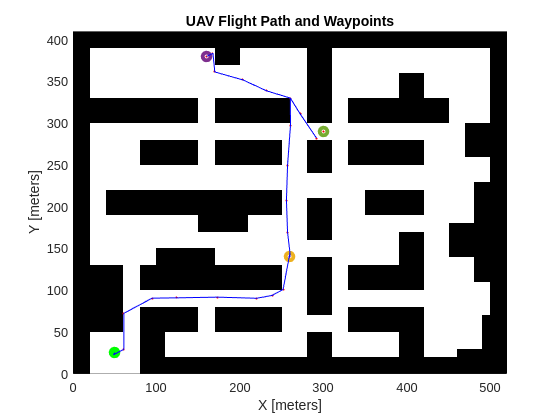

f2 = figure(2); clf;
map = load(sprintf('trajectories/%s.mat', trajectory.map)).(sprintf('%s', trajectory.map));
hold on;
show(map);
plot(trajectory.path(:,1), trajectory.path(:,2), 'r.', 'MarkerSize', 5)
plot(trajectory.start(1), trajectory.start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(trajectory.waypoints(:,1))
   plot(trajectory.waypoints(i,1), trajectory.waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(trajectory.path)-1
    plot([trajectory.path(i-1,1) trajectory.path(i, 1)], [trajectory.path(i-1,2) trajectory.path(i, 2)], 'b');
end
hold off;
title("UAV Flight Path and Waypoints")

clear('map', 'i', 'f2');

## 4. Setup simulation params

% stop measure on the simulation, in general it should stop before this
sim_params.max_sim_time = 4000;

% performance thresholds %%%% max_pos_err calculation is incorrect (does
% not account for time offset, needs updated)
sim_params.perf_param_thresh.max_pos_err  = 10; % this is check in the simulation
sim_params.perf_param_thresh.min_soc      = .2; % this is check in the simulation
sim_params.perf_param_thresh.min_v        = uav.battery.EOD * 1.1; % this is checked in the simulation
sim_params.perf_param_thresh.min_soh_batt = uav.battery.Q * .6; % this is checked after %% can this even be done?
sim_params.perf_param_thresh.avg_pos_err  = 2.8; % this is checked after
sim_params.perf_param_thresh.pos_err_var  = 10; % check this 

% controller and filter estimation parameters, initial conditions for the UAV
sim_params.controllers         = load('params/controllers.mat').controllers;
sim_params.initial_conditions  = load('params/IC_HoverAt10ftOcto.mat').IC;

sim_params.battery_estimator   = load('estimation/batteryestimator').batteryestimator;
sim_params.battery_estimator.Qinit = uav.battery.Q;
if uav.battery.v0 < 4.3
    sim_params.battery_estimator.soc_ocv = interp1([sim_params.battery_estimator.soc_ocv(1) sim_params.battery_estimator.soc_ocv(end)], [3.04 4.2], sim_params.battery_estimator.soc_ocv);
end

if strcmp(uav.uav.common_name, 'default')
    sim_params.position_estimator  = load('estimation/positionestimator').PositionEstimator;
    sim_params.motor_estimator     = load('estimation/MotorEstimator').MotorEstimator;
end

sim_params.initial_conditions.X = trajectory.start(1);
sim_params.initial_conditions.Y = trajectory.start(2);

## 5. Load process data

- environment (wind)

- degradation (battery, motors)

### This will get all processes of a given type (degradation or environment)

process_type = 'degradation';
description = 'continuous';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES));
process_tb = process_tb(contains(string(process_tb.description), description),:)

process_tb = 13×9 table
    id         type           subtype1             subtype2            id_1    type_id             description                        source                            parameters            
    __    _______________    ___________    _______________________    ____    _______    _____________________________    _____________________________    __________________________________

    1     {'degradation'}    {'battery'}    {'capacitance'        }      5        1       {'continuous usage based v1'}    {'NASA prognostics data set'}    {1×1 org.postgresql.util.PGobject}
    1     {'degradation'}    {'battery'}    {'capacitance'        }      6        1       {'cont

proc_tb = process_tb(contains(string(process_tb.subtype1), 'battery'), :)

proc_tb = 5×9 table
    id         type           subtype1             subtype2            id_1    type_id             description                        source                            parameters            
    __    _______________    ___________    _______________________    ____    _______    _____________________________    _____________________________    __________________________________

    1     {'degradation'}    {'battery'}    {'capacitance'        }     5         1       {'continuous usage based v1'}    {'NASA prognostics data set'}    {1×1 org.postgresql.util.PGobject}
    1     {'degradation'}    {'battery'}    {'capacitance'        }     6         1       {'continuo

proc_tb = proc_tb((contains(string(proc_tb.description), "v3") & contains(string(proc_tb.subtype2), "capacitance")) | (contains(string(proc_tb.description), "v2") & contains(string(proc_tb.subtype2), "resistance")),:)

proc_tb = 2×9 table
    id         type           subtype1             subtype2            id_1    type_id             description                        source                            parameters            
    __    _______________    ___________    _______________________    ____    _______    _____________________________    _____________________________    __________________________________

    1     {'degradation'}    {'battery'}    {'capacitance'        }     7         1       {'continuous usage based v3'}    {'NASA prognostics data set'}    {1×1 org.postgresql.util.PGobject}
    2     {'degradation'}    {'battery'}    {'internal resistance'}     9         2       {'continuo

for i = 1:height(proc_tb)
    params = proc_tb(i, 'parameters').parameters{1}
    res = jsondecode(string(params));
    uav.battery.(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
end


params =

{"q_coef": [-3.964636685641575e-07,9.164360283399920e-05,21.508765867439045]}


params =

{"r_coef": [1.574235975754939e-09,1.318054396279285e-05,0.0011]}



proc_tb =  process_tb(contains(string(process_tb.subtype1), 'motor'), :)

proc_tb = 8×9 table
    id         type          subtype1            subtype2            id_1    type_id             description                   source                       parameters            
    __    _______________    _________    _______________________    ____    _______    _____________________________    ___________________    __________________________________

    3     {'degradation'}    {'motor'}    {'internal resistance'}     10        3       {'continuous usage based v1'}    {'experimentation'}    {1×1 org.postgresql.util.PGobject}
    3     {'degradation'}    {'motor'}    {'internal resistance'}     11        3       {'continuous usage based v2'}    {'experimentati

for i = 1:height(proc_tb)
    params = proc_tb(i, 'parameters').parameters{1}
    res = jsondecode(string(params));
    uav.motors(i).(sprintf("%s",string(fieldnames(res)))) = res.(sprintf("%s", string(fieldnames(res))))';
end


params =

{"r_coef": [2.91940637233805e-08,2.51296556203587e-05,0.267534750087853]}


params =

{"r_coef": [5.03203644599304e-08,4.52482807162499e-05,0.263602775657784]}


params =

{"r_coef": [1.17951512300631e-08,0.000126153758759434,0.267388743143241]}


params =

{"r_coef": [2.02884959369022e-08,0.000129703751104999,0.263620266868153]}


params =

{"r_coef": [2.00949753003282e-08,0.000120820568496029,0.266781531939975]}


params =

{"r_coef": [4.93684103069012e-08,3.71391496681986e-05,0.266256395026620]}


params =

{"r_coef": [1.81206612180933e-08,7.09090300154583e-05,0.265032260682462]}


params =

{"r_coef": [2.12003523904136e-08,9.64408128994080e-05,0.265046939982291]}



process_type = 'environment';
process_tb = select(conn, eval(api.matlab.process.LOAD_ALL_PROCESSES))  

process_tb = 1×9 table
    id         type          subtype1    subtype2    id_1    type_id                                    description                                                  source                             parameters            
    __    _______________    ________    ________    ____    _______    ____________________________________________________________________________    ________________________________    __________________________________

    4     {'environment'}    {'wind'}    {'gust'}     4         4       {'simulated wind gusts through direct application of force to the airframe'}    {'generated by experimentation'}    {1×1 org.postgresql.util.PGobject}


for i = 1:height(process_tb)
    params = process_tb(i, 'parameters').parameters{1}
    res = jsondecode(string(params));
    fn = fieldnames(res);
    for j = 1:length(fn)
        processes.(sprintf("%s", process_type)).(sprintf("%s", process_tb(i, 'subtype1').subtype1{1})).(sprintf("%s", process_tb(i, 'subtype2').subtype2{1})).(sprintf("%s", fn{j})) = res.(fn{j})
    end
end


params =

{"x": [1.0, 0.25], "y": [0.5, 0.5], "z": [0.1, 0.1]}



processes = struct with fields:
    environment: [1×1 struct]


processes = struct with fields:
    environment: [1×1 struct]


processes = struct with fields:
    environment: [1×1 struct]


clear('description', 'i', 'j', 'params', 'proc_tb', 'process_tb', 'process_type', 'res', 'fn');

## 5. Simulate

tic
if strcmp(uav.uav.common_name, 'tarot t18 uav')
    sim('simulink/uav_simulation_tarot.slx');
else 
    sim('simulink/uav_simulation.slx');
end
toc

Elapsed time is 111.804719 seconds.


#### calculate dt_stop

dt_stop = dt_start + minutes(time.Data(end, 1))

dt_stop = datetime
   15-Jul-2022 16:08:24


## 5a. check stop codes and system performance parameter thresholds

- stop codes 1-4 are checked in simulation, 5-6 are checked after

stop_code = max(find(any(stop_codes.Data(:,:))))

stop_code = 4

string(stop_code_tb.description(stop_code_tb.id==stop_code))

ans = "arrival success"

#### check the average position error threshold

if mean(errors.euclidean_pos_err.Data) > sim_params.perf_param_thresh.avg_pos_err
    stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'average position error'))
end

#### (move to preflight: check the minimum state of health for the battery threshold - battery.Q)

if  uav.battery.Q < sim_params.perf_param_thresh.min_soh_batt
    stop_code = stop_code_tb.id(strcmp(stop_code_tb.description, 'low soh (battery)'))
end

## 6. Update component degradation parameters

- battery

if strcmp(string(uav.uav.common_name), "tarot t18 uav")
    %uav.battery.age = 0;
    avg_current = abs(mean(battery.battery_true.i.Data(:)));
    flight_time = time.Data(end)/60; % this is in minutes
    amp_hours = avg_current * flight_time;
    uav.battery.age = uav.battery.age + amp_hours;

- [TODO] implement estimators and pull covariance instead of "factory" 2% 

    Q_mu = polyval(uav.battery.q_coef, uav.battery.age);
    Q_std = .02*Q_mu;
    
    R0_mu = polyval(uav.battery.r_coef, uav.battery.age);
    R0_std = .02*R0_mu;
    
    uav.battery.Q = normrnd(Q_mu, Q_std);
    uav.battery.R0 = normrnd(R0_mu, R0_std);

charge =   Simulink.SimulationOutput:

     battery_state_params: [1x1 struct] 
                     time: [1x1 timeseries] 
                     tout: [23978x1 double] 
                        u: [1x1 timeseries] 

       SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
             ErrorMessage: [0x0 char] 


- motors

    for i = 1:length(uav.motors)
        %uav.motors(i).age = 0;
        avg_current = abs(mean(motors.(sprintf('m%d',i)).current.Data(:)));
        uav.motors(i).age = uav.motors(i).age + avg_current * flight_time;
        m_mu = polyval(uav.motors(i).r_coef, uav.motors(i).age);
        m_std = .02*m_mu;
        uav.motors(i).Req = normrnd(m_mu, m_std);
    end
end

- the uav

%uav.uav.age = 0;
uav.uav.age = uav.uav.age + amp_hours;

## 6a. charge the battery

persist the battery state

uav.battery.v = battery.battery_true.v.Data(end);
uav.battery.z = battery.battery_true.z.Data(end);

standard charging practice is 1C

u = -22; %-uav.battery.Q;  % Q degrades but u should remain the factory value of 22 for the case of the tarot
charge = sim('continuous_battery.slx')
uav.battery.v = charge.battery_state_params.v.Data(end);
uav.battery.z = charge.battery_state_params.z.Data(end);
avg_current = abs(mean(charge.u.Data));
charge_time = charge.time.Data(end)/3600; % this is in seconds
amp_hours = avg_current * charge_time;
charge_discount = .9;
uav.battery.age = uav.battery.age + (amp_hours * charge_discount);

### Update degradation parameters

- charging the battery doesnt degrade it as much as discharging

Q_mu = polyval(uav.battery.q_coef, uav.battery.age);
Q_std = .02*Q_mu;

R0_mu = polyval(uav.battery.r_coef, uav.battery.age);
R0_std = .02*R0_mu;
uav.battery.Q = normrnd(Q_mu, Q_std);
uav.battery.R0 = normrnd(R0_mu, R0_std);

## 7. Update the asset age in the database 

% conn = db_connect('nasadb');

var_names = 1×30 string array
    "id"    "stop_code"    "z_start"    "z_end"    "v_start"    "v_end"    "m1_avg_current"    "m2_avg_current"    "m3_avg_current"    "m4_avg_current"    "m5_avg_current"    "m6_avg_current"    "m7_avg_current"    "m8_avg_current"    "avg_pos_err"    "max_pos_err"    "std_pos_err"    "avg_ctrl_err"    "max_ctrl_err"    "std_ctrl_err"    "distance"    "flight_time"    "avg_current"    "amp_hours"    "dt_start"    "dt_stop"    "trajectory_id"    "uav_id"    "flight_num"    "group_id"


conn = database(db_name, username, password);

execute(conn, eval(api.matlab.assets.UPDATE_BATTERY_AGE));
execute(conn, eval(api.matlab.assets.UPDATE_UAV_AGE));
for i = 1:length(uav.motors)
    execute(conn, eval(api.matlab.assets.UPDATE_MOTOR_AGE))
end
clear('charge', 'avg_current', 'charge_time', 'amp_hours', 'Q_mu', 'Q_std', 'R0_mu', 'R0_std', 'm_mu', 'm_std', 'u', 'flight_time');

flight_summary_tb = 1×29 table
    stop_code    z_start     z_end     v_start    v_end     m1_avg_current    m2_avg_current    m3_avg_current    m4_avg_current    m5_avg_current    m6_avg_current    m7_avg_current    m8_avg_current    avg_pos_err    max_pos_err    std_pos_err    avg_ctrl_err    max_ctrl_err    std_ctrl_err    distance    flight_time    avg_current    amp_hours          dt_start                dt_stop           trajectory_id    uav_id    flight_num    group_id
    _________

## 8. Insert summary data into the db

% get the variable names, but note "id" isn't used
var_names = get_column_names(conn, 'flight_summary_tb')
flight_summary_tb = table(max(find(any(stop_codes.Data(:,:)))), ...
                          battery.battery_true.z.Data(1), ...
                          battery.battery_true.z.Data(end), ...
                          battery.battery_true.v.Data(1), ...

var_names = 1×22 string array
    "id"    "flight_id"    "q_deg"    "q_var"    "r_deg"    "r_var"    "m1_deg"    "m1_var"    "m2_deg"    "m2_var"    "m3_deg"    "m3_var"    "m4_deg"    "m4_var"    "m5_deg"    "m5_var"    "m6_deg"    "m6_var"    "m7_deg"    "m7_var"    "m8_deg"    "m8_var"


                          battery.battery_true.v.Data(end), ...
                          mean(motors.m1.current), ...
                          mean(motors.m2.current), ...
                          mean(motors.m3.current), ...

var_names = 1×11 cell array
    {'flight_id'}    {'q_deg'}    {'r_deg'}    {'m1_deg'}    {'m2_deg'}    {'m3_deg'}    {'m4_deg'}    {'m5_deg'}    {'m6_deg'}    {'m7_deg'}    {'m8_deg'}


                          mean(motors.m4.current), ...
                          mean(motors.m5.current), ...
                          mean(motors.m6.current), ...
                          mean(motors.m7.current), ...
                          mean(motors.m8.current), ...
                          mean(errors.euclidean_pos_err), ...
                          max(errors.euclidean_pos_err), ...
                          std(errors.euclidean_pos_err), ...
                          mean(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          max(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          std(sqrt(errors.ctrl_err.x_error.Data.^2 + errors.ctrl_err.y_error.Data.^2)), ...
                          round(calculatedistance([position.true.Data(:,1) position.true.Data(:,2)]), 4), ...

flight_degradation_tb = 1×11 table
    flight_id    q_deg       r_deg      m1_deg     m2_deg     m3_deg     m4_deg     m5_deg     m6_deg     m7_deg     m8_deg 
    _________    ______    _________    _______    _______    _______    _______    _______    _______    _______    _______

        2        21.522    0.0018374    0.26111    0.25984    0.26591    0.26352    0.27669    0.26847    0.25999    0.26598


                          time.Time(end)/60, ...
                          mean(battery.battery_true.i.Data), ...
                          mean(battery.battery_true.i.Data)*time.Time(end)/60/60, ...
                          dt_start, ...
                          dt_start + minutes(time.Time(end)/60), ...
                          trajectory.id, ...
                          uav.id, ...
                          flight_num, ...
                          group_id, ...
                          'VariableNames',  cellstr(var_names(1,2:end)))
% write the data to the database

ans = 120.0024

sqlwrite(conn, 'flight_summary_tb', flight_summary_tb);

## 9. Get the degradation data and insert it

% get var names [DEPRECIATED - see new table definition]
var_names = get_column_names(conn, 'flight_degradation_tb')

ans = 40

#### flight_id refers to the id field of the flight_summary_tb. This is pulled from the beginning

#### also, on this flight we are only inserting 4 parameters, the 4 required parameters to use this table

var_names = {'flight_id' 'q_deg' 'r_deg' 'm1_deg' 'm2_deg' 'm3_deg' 'm4_deg' 'm5_deg' 'm6_deg' 'm7_deg' 'm8_deg'}
flight_degradation_tb = table(flight_id, ...

ans = 120.0024

                              uav.battery.Q, ...
                              uav.battery.R0, ...
                              uav.motors(1).Req, ...
                              uav.motors(2).Req, ...
                              uav.motors(3).Req, ...

battery_tt = 821×9 timetable
     Time     battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var
    ______    ______________    ______________    ______________    ______________    _____________    _____________    _____________    _________________    _________________

    0 sec           22.2                 1            0.0011           0.70206             22.2                 1            0.0011                 0                 0.003    
    1 sec         22.118            0.9992            0.0011        

                              uav.motors(4).Req, ...
                              uav.motors(5).Req, ...
                              uav.motors(6).Req, ...
                              uav.motors(7).Req, ...
                              uav.motors(8).Req, ...
                              'VariableNames', var_names)
clear('var_names');

errors_tt = 821×5 timetable
     Time     euclidean_pos_err    x_pos_err    y_pos_err    x_ctrl_err    y_ctrl_err
    ______    _________________    _________    _________    __________    __________

    0 sec         0.075979          0.060271     0.046263      -0.1678      -0.41304 
    1 sec           0.3533           0.23748      0.26158    -0.024136      -0.44832 
    2 sec          0.59564           0.39387      0.44682     -0.42926      -0.38532 
    3 sec          0.51442           0.33828      0.38755     -0.42122      -0.45724 
    4 sec          0.31461           0.17163      0.26367     -0.11139      -0.12394 
    5 sec          0.29371         -0.094863      0.27797     -

% write the data to the database
sqlwrite(conn, 'flight_degradation_tb', flight_degradation_tb);


## 10. Get the telemetry data

#### There are multiple different sample rates

- The battery is sampled at 1hz

t_batt = battery.battery_true.v.Time;
1/mean(diff(t_batt))

- airframe dynamics at 40hz

t_dynamics = errors.ctrl_err.x_error.Time;

environment_tt = 821×3 timetable
     Time     wind_gust_x    wind_gust_y    wind_gust_z
    ______    ___________    ___________    ___________

    0 sec          2.539        0.61969        0.93678 
    1 sec         1.6669         1.9036        0.59645 
    2 sec         2.7588       -0.40135        0.24748 
    3 sec           1.04          2.099        0.42238 
    4 sec      -0.010902         1.9341       -0.24051 
    5 sec         1.9859     -0.0055669         1.2727 
    6 sec         2.0148        0.30334        0.23735 
    7 sec         2.1797         4.0761         1.3366 
    8 sec      -0.035476         1.8512        0.36701 
    9 sec         1.6424       -0.35225     

1/mean(diff(t_dynamics))

- Other variables step with the simulation

- That small difference needs accounted for!

t_sim = time.Time;

motors_tt = 821×32 timetable
     Time     m1_rpm    m1_torque    m1_current    m1_vref    m2_rpm    m2_torque    m2_current    m2_vref    m3_rpm    m3_torque    m3_current    m3_vref    m4_rpm    m4_torque    m4_current    m4_vref    m5_rpm    m5_torque    m5_current    m5_vref    m6_rpm    m6_torque    m6_current    m6_vref    m7_rpm    m7_torque    m7_current    m7_vref    m8_rpm    m8_torque    m8_current    m8_vref
    ___

1/mean(diff(t_sim))
clear('t_batt', 't_dynamics', 't_sim');

### Battery data

sample_rate = 1;

battery_tt = sync_telemetry_data(battery, sample_rate, time.Time(:))

### Errors data

errors_tt = sync_telemetry_data(errors, sample_rate, time.Time(:));
errors_tt.Properties.VariableNames{'pos_err_x_pos_err'} = 'x_pos_err';
errors_tt.Properties.VariableNames{'pos_err_y_pos_err'} = 'y_pos_err';
errors_tt.Properties.VariableNames{'ctrl_err_x_error'}  = 'x_ctrl_err';

position_tt = 821×6 timetable
     Time     x_pos_gps    y_pos_gps    z_pos_gps    x_pos_true    y_pos_true    z_pos_true
    ______    _________    _________    _________    __________    __________    __________

    0 sec      50.108       25.367       2.5482            50            25             3  
    1 sec      49.878       25.197       3.2443        50.091        25.011        3.1742  
    2 sec      50.196        24.93       3.2303        50.161        24.991        3.2566  
    3 sec      50.159       24.843       3.3192        50.076        24.774        3.2493  
    4 sec      49.874       24.398       3.3688        49.934        24.538        3.2022  
  

errors_tt.Properties.VariableNames{'ctrl_err_y_error'}  = 'y_ctrl_err';
errors_tt

### Environment data

environment_tt = sync_telemetry_data(environment, sample_rate, time.Time(:));
environment_tt.Properties.VariableNames{'wind_gust-1'}  = 'wind_gust_x';
environment_tt.Properties.VariableNames{'wind_gust-2'}  = 'wind_gust_y';
environment_tt.Properties.VariableNames{'wind_gust-3'}  = 'wind_gust_z';
environment_tt

### Motor data

motors_tt = sync_telemetry_data(motors, sample_rate, time.Time(:))

### Position data

position_tt = sync_telemetry_data(position, sample_rate, time.Time(:));

velocity_tt = 821×6 timetable
     Time     x_vel_gps    y_vel_gps    z_vel_gps    x_vel_true    y_vel_true     z_vel_true
    ______    _________    _________    _________    __________    ___________    __________

    0 sec     0.0086217    0.0031877    -0.013077            0               0             0
    1 sec       0.14268     0.001787      0.11856      0.14297     -3.7524e-05       0.13421
    2 sec     -0.035211    -0.056645     0.034277    -0.041165       -0.067114      0.036257
    3 sec      -0.11003     -0.34006    -0.044041     -0.10273        -0.34333     -0.038892
    4 sec      -0.17076     -0.11065    -0.041876     -0.16381        -0.10603     -0.05

position_tt.Properties.VariableNames{'gps-1'}  = 'x_pos_gps';
position_tt.Properties.VariableNames{'gps-2'}  = 'y_pos_gps';
position_tt.Properties.VariableNames{'gps-3'}  = 'z_pos_gps';
position_tt.Properties.VariableNames{'true-1'}  = 'x_pos_true';
position_tt.Properties.VariableNames{'true-2'}  = 'y_pos_true';

flight_telemetry_tb = 821×61 timetable
      dt      battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var    wind_gust_x    wind_gust_y    wind_gust_z    m1_rpm    m1_torque    m1_current    m1_vref    m2_rpm    m2_torque    m2_current    m2_vref    m3_rpm    m3_torque    m3_current    m3_vref    m4_rpm    m4_torque    m4_current    m4_vref    m5_rpm    m5_torque

position_tt.Properties.VariableNames{'true-3'}  = 'z_pos_true';
position_tt

### Velocity data

velocity_tt = sync_telemetry_data(velocity, sample_rate, time.Time(:));
velocity_tt.Properties.VariableNames{'gps-1'}  = 'x_vel_gps';
velocity_tt.Properties.VariableNames{'gps-2'}  = 'y_vel_gps';

flight_telemetry_tb = 821×61 timetable
              dt               battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var    wind_gust_x    wind_gust_y    wind_gust_z    m1_rpm    m1_torque    m1_current    m1_vref    m2_rpm    m2_torque    m2_current    m2_vref    m3_rpm    m3_torque    m3_current    m3_vref    m4_rpm    m4_torque    m4_current    m4_vref    m5_rpm    

velocity_tt.Properties.VariableNames{'gps-3'}  = 'z_vel_gps';
velocity_tt.Properties.VariableNames{'true-1'}  = 'x_vel_true';
velocity_tt.Properties.VariableNames{'true-2'}  = 'y_vel_true';
velocity_tt.Properties.VariableNames{'true-3'}  = 'z_vel_true';
velocity_tt

### **Merge the timetables**

flight_telemetry_tb = [battery_tt environment_tt motors_tt errors_tt position_tt velocity_tt];
clear('battery_tt', 'environment_tt', 'motors_tt', 'errors_tt', 'position_tt', 'velocity_tt');
flight_telemetry_tb.Properties.DimensionNames{1} = 'dt';
flight_telemetry_tb

### Convert the time vector duration to a datetime

dt_start.Format = 'MM-dd-uuuu HH:mm:ss.SSS';
dt_stop.Format = 'MM-dd-uuuu HH:mm:ss.SSS';
time_vec = datetime([dt_start: seconds(1/sample_rate) : dt_stop]');
flight_telemetry_tb.dt = time_vec

### Impute any missing values

- Usually this isn't required, but there are edge cases

missing_v = sum(ismissing(flight_telemetry_tb.battery_true_v));
missing_z = sum(ismissing(flight_telemetry_tb.battery_true_z));
missing_i = sum(ismissing(flight_telemetry_tb.battery_true_i));
vals_v = flight_telemetry_tb.battery_true_v;
vals_z = flight_telemetry_tb.battery_true_z;
vals_i = flight_telemetry_tb.battery_true_i;
poly_v = polyfit(1:1:length(vals_v), vals_v, 1);
poly_z = polyfit(1:1:length(vals_z), vals_z, 1);


idx_v =

  0×1 empty double column vector



poly_i = polyfit(1:1:length(vals_i), vals_i, 1);


idx_z =

  0×1 empty double column vector



missing_vals_v = zeros(1, missing_v);


idx_i =

  0×1 empty double column vector



missing_vals_z = zeros(1, missing_z);
missing_vals_i = zeros(1, missing_i);
for i = 1:missing_v
    missing_vals_v(1,i) = polyval(poly_v, i);
    missing_vals_z(1,i) = polyval(poly_z, i);
    missing_vals_i(1,i) = polyval(poly_i, i);
end

idx_v = find(ismissing(flight_telemetry_tb.battery_true_v))

flight_telemetry_tb = 821×63 table
              dt               battery_true_v    battery_true_z    battery_true_r    battery_true_i    battery_hat_v    battery_hat_z    battery_hat_r    battery_hat_z_var    battery_hat_r_var    wind_gust_x    wind_gust_y    wind_gust_z    m1_rpm    m1_torque    m1_current    m1_vref    m2_rpm    m2_torque    m2_current    m2_vref    m3_rpm    m3_torque    m3_current    m3_vref    m4_rpm    m4_torque    m4_current    m4_vref    m5_rpm    m5_t

idx_z = find(ismissing(flight_telemetry_tb.battery_true_z))
idx_i = find(ismissing(flight_telemetry_tb.battery_true_i))

flight_telemetry_tb.flight_id = repmat(flight_id, height(flight_telemetry_tb), 1);

% for i = 1:length(idx_z)
%     flight_telemetry_tb.battery_true_v(idx_z(i)) = polyval(poly_v, 20+i);
%     flight_telemetry_tb.battery_true_z(idx_z(i)) = polyval(poly_z, 20+i);
%     flight_telemetry_tb.battery_true_i(idx_z(i)) = polyval(poly_i, 20+i);
% end
flight_telemetry_tb = timetable2table(flight_telemetry_tb)

### Insert the telemetry data into the database

% write the data to the database
sqlwrite(conn, 'flight_telemetry_tb', flight_telemetry_tb);
clear('missing_v', 'missing_z', 'missing_i', 'x', 'vals_v', 'vals_z', 'vals_i', 'poly_v', 'poly_z', 'poly_i', 'missing_vals_v', 'missing_vals_z', 'missing_vals_i', 'idx_v', 'idx_z', 'idx_i', 'dt_start', 'dt_stop', 'time_vec', 'environment', 'errors', 'flight_degradation_tb', 'flight_summary_tb', 'motors', 'position', 'stop_codes', 'time', 'tout', 'velocity', 'i', 'stop_code', 'trajectory', 'battery');
